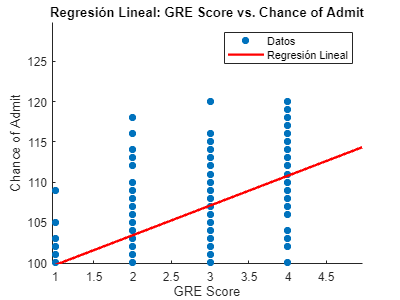

% Leer los datos del archivo Excel
filename = 'Admission_Predict.xlsx';
sheet = 1; % Si la hoja tiene un nombre específico, reemplaza esto con el nombre de la hoja

% Leer solo las columnas 'Posibilidad de admisión' y 'GRE'
data = xlsread(filename, sheet, 'C:D');

% Extraer los datos en variables individuales
Chance_of_Admit = data(:, 1);
GRE_Score = data(:, 2);

% Ajuste del modelo de regresión lineal
coefficients = polyfit(GRE_Score, Chance_of_Admit, 1);

% Obtención de los valores predichos por el modelo
GRE_Score_pred = min(GRE_Score):max(GRE_Score);
Chance_of_Admit_pred = polyval(coefficients, GRE_Score_pred);

% Gráfico de dispersión y línea de regresión
figure;
scatter(GRE_Score, Chance_of_Admit, 'filled');
hold on;
plot(GRE_Score_pred, Chance_of_Admit_pred, 'r', 'LineWidth', 2);
hold off;
xlabel('GRE Score');
ylabel('Chance of Admit');
title('Regresión Lineal: GRE Score vs. Chance of Admit');
legend('Datos', 'Regresión Lineal');


% Mostrar información sobre el modelo
disp(['Coeficientes de la regresión: ' num2str(coefficients)]);

Coeficientes de la regresión: 3.69134       96.013
